clear; clc; close all

% Riproducibilità
rng(42);

# Obiettivo

Lo scopo principale di questo progetto è creare una CNN che provi ad identificare il "tipo" di sfocatura applicata all'immagine, dove con "tipo" si intende il kernel con cui è stata convoluta l'immagine. 

Nel dettaglio sono stati presi in considerazione i seguenti kernel:

%Lista kernel normalizzati

fprintf("UNIFORMI\n");

UNIFORMI



fprintf('Box_3\n');

Box_3


fprintf("-\n");

-


disp(ones(3,3)/9)

    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111



fprintf("-\n");

-



fprintf('Box_5\n');

Box_5


fprintf("-\n");

-


disp(ones(5,5)/25)

    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400



fprintf("-");

-

fprintf("---------------------------------------------------\n");

---------------------------------------------------



fprintf("GAUSSIANI\n");

GAUSSIANI



fprintf('Gauss_3\n');

Gauss_3


fprintf("-\n");

-


disp([
    1 2 1;
    2 4 2;
    1 2 1
]/16)

    0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625



fprintf("-\n");

-



fprintf('Gauss_5\n');

Gauss_5


fprintf("-\n");

-


disp([
    1  4  6  4  1;
    4 16 24 16  4;
    6 24 36 24  6;
    4 16 24 16  4;
    1  4  6  4  1
]/256)

    0.0039    0.0156    0.0234    0.0156    0.0039
    0.0156    0.0625    0.0938    0.0625    0.0156
    0.0234    0.0938    0.1406    0.0938    0.0234
    0.0156    0.0625    0.0938    0.0625    0.0156
    0.0039    0.0156    0.0234    0.0156    0.0039



fprintf("-");

-

fprintf("---------------------------------------------------\n");

---------------------------------------------------



fprintf("FORME\n");

FORME



fprintf('Circ_5\n');

Circ_5


fprintf("-\n");

-


disp([
    0 0 1 0 0;
    0 1 1 1 0;
    1 1 1 1 1;
    0 1 1 1 0;
    0 0 1 0 0
]/13)

         0         0    0.0769         0         0
         0    0.0769    0.0769    0.0769         0
    0.0769    0.0769    0.0769    0.0769    0.0769
         0    0.0769    0.0769    0.0769         0
         0         0    0.0769         0         0



fprintf("-\n");

-



fprintf('Cross_5\n');

Cross_5


fprintf("-\n");

-


disp([
    0 0 1 0 0;
    0 0 1 0 0;
    1 1 1 1 1;
    0 0 1 0 0;
    0 0 1 0 0
]/9)

         0         0    0.1111         0         0
         0         0    0.1111         0         0
    0.1111    0.1111    0.1111    0.1111    0.1111
         0         0    0.1111         0         0
         0         0    0.1111         0         0



fprintf("-");

-

fprintf("---------------------------------------------------\n");

---------------------------------------------------



fprintf("LINEE\n");

LINEE



fprintf('D\n');

D


fprintf("-\n");

-


disp(eye(5)/5)

    0.2000         0         0         0         0
         0    0.2000         0         0         0
         0         0    0.2000         0         0
         0         0         0    0.2000         0
         0         0         0         0    0.2000



fprintf("-\n");

-



fprintf('H\n');

H


fprintf("-\n");

-


disp([
    0 0 0 0 0;
    0 0 0 0 0;
    1 1 1 1 1;
    0 0 0 0 0;
    0 0 0 0 0
]/5)

         0         0         0         0         0
         0         0         0         0         0
    0.2000    0.2000    0.2000    0.2000    0.2000
         0         0         0         0         0
         0         0         0         0         0



fprintf("-\n");

-



fprintf('V\n');

V


fprintf("-\n");

-


disp([
    0 0 1 0 0;
    0 0 1 0 0;
    0 0 1 0 0;
    0 0 1 0 0;
    0 0 1 0 0
]/5)

         0         0    0.2000         0         0
         0         0    0.2000         0         0
         0         0    0.2000         0         0
         0         0    0.2000         0         0
         0         0    0.2000         0         0



fprintf("-");

-

fprintf("---------------------------------------------------\n");

---------------------------------------------------



fprintf("ALTRI\n");

ALTRI



fprintf("Originale\n");

Originale


fprintf("-\n");

-


disp([
    0 0 0;
    0 1 0;
    0 0 0;
    ])

     0     0     0
     0     1     0
     0     0     0



fprintf("-\n");

-



fprintf("Median_5: restituisce la mediana della finestra");

Median_5: restituisce la mediana della finestra

# EDA

Il dataset usato è "[COCO 2017 Unlabeled Images](https://cocodataset.org/#download)". Questa scelta deriva dall'obiettivo generale, infatti non si vuole classificare un qualcosa presente nell'immagine ma una caratteristica di quest'ultima e quindi sorge la necessità di avere un dataset molto vario per permettere una buona generalizzazione. Per capire appunto la capacità di generalizzazione è stato creato inoltre un secondo dataset di test (combinando "[Sea Animals Image Dataset🌊](https://www.kaggle.com/datasets/vencerlanz09/sea-animals-image-dataste)" e "[Count Coins Image dataset](https://www.kaggle.com/datasets/balabaskar/count-coins-image-dataset)") da usare in parallelo allo split apposito del dataset principale.

In ogni caso tutti i dataset incriminati sono composti da immagini più o meno nitide di dimensioni variabili, per adattarle alla rete si è quindi rivelato necessario effettuare delle operazioni di pre-processing. Le 2 principali sono:

- Togliere le immagini già sfocate in partenza per evitare "contaminazioni" (seguendo "[Blur detection with OpenCV](https://pyimagesearch.com/2015/09/07/blur-detection-with-opencv/)") 

- Effettuare la convoluzione e ridimensionare il risultato

Per una singola immagine si può riassumere il flusso di elaborazione come:

- Apri immagine in scala di grigi

- Se troppo piccola/sfocata scartala

- Applica la convoluzione con un kernel casuale (la grandezza del dataset garantisce una distribuzione abbastanza uniforme)

- Ritaglia una porzione di dimensione 224x224 al centro (per evitare di includere eventuali artefatti sui bordi)

- Salva risultato

Dopo aver completato l'elaborazione si è arrivati a questi 2 dataset:

% Caricamento immagini
path = fullfile('Dataset', 'Da usare');
imgs = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

path2 = fullfile('Dataset', 'Da usare1');
imgs2 = imageDatastore(path2, "IncludeSubfolders", true, "LabelSource", "foldernames");

fprintf("DATASET PRINCIPALE");

DATASET PRINCIPALE

fprintf('Numero totale di immagini: %d\n', numel(imgs.Labels));

Numero totale di immagini: 60000


fprintf('Training: %d (70%%)\n', numel(imgs.Labels) * 0.7);

Training: 42000 (70%)


fprintf('Validazione: %d (15%%)\n', numel(imgs.Labels) * 0.15);

Validazione: 9000 (15%)


fprintf('Test: %d (15%%)\n\n', numel(imgs.Labels) * 0.15);

Test: 9000 (15%)



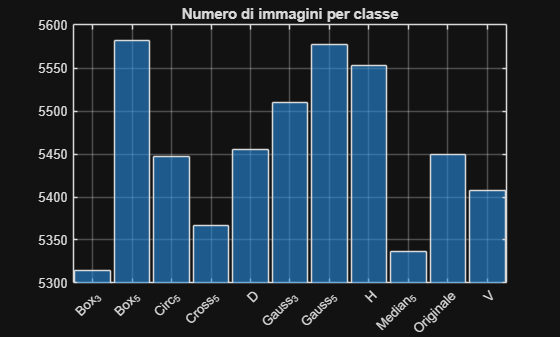


% Immagini per classe
figure;

countcats(imgs.Labels);
histogram(imgs.Labels);

title('Numero di immagini per classe');
ylim([5300, 5600]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

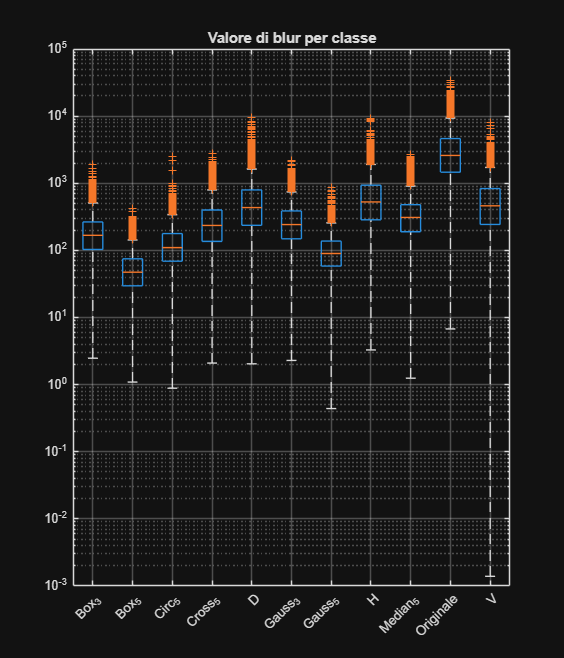



% Boxplot del laplaciano per classe
figure;

T = readtable(fullfile(path, 'blur_scores.csv'), ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

T.kernel = categorical(T.kernel);
T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));

boxplot(T.blur_score_dopo, T.kernel);
set(gcf, 'Position', [100, 100, 600, 700]);
set(gca,'YScale', 'log')

ax = gca;
ax.TickLabelInterpreter = 'tex';

title('Valore di blur per classe');

xtickangle(45);
grid on;

I valori sull'asse delle ordinate sono calcolati con il metodo citato prima per trovare le immagini sfocate, però dopo aver applicato la convoluzione.

fprintf('%s\n', repmat(' ', 1, 80));

% Altro dataset

fprintf('DATASET CONTRO-TEST');

DATASET CONTRO-TEST

fprintf('Numero totale di immagini: %d\n', numel(imgs2.Labels));

Numero totale di immagini: 1360


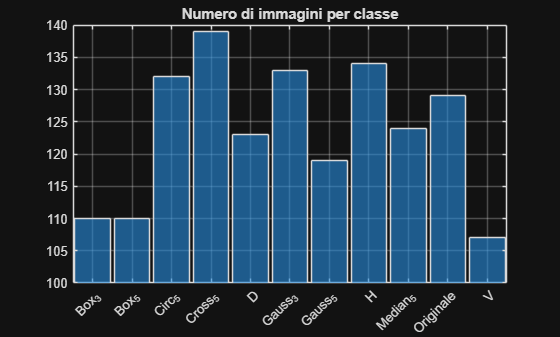


% Immagini per classe
figure;

countcats(imgs2.Labels);
histogram(imgs2.Labels);

title('Numero di immagini per classe');
ylim([100, 140]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

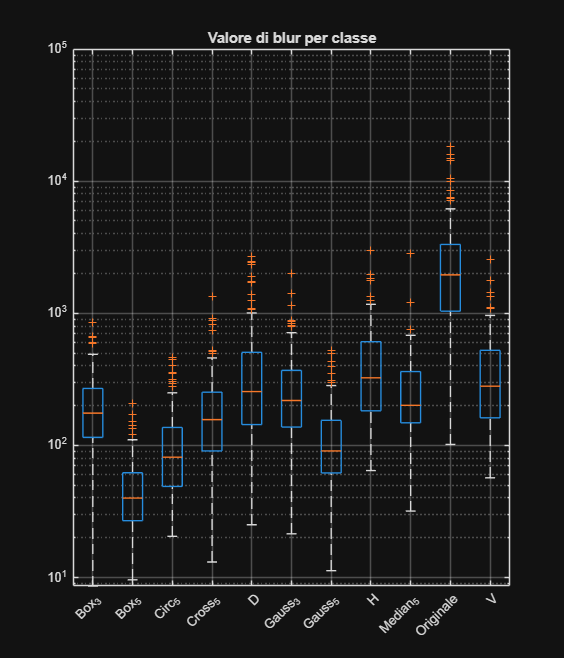



% Boxplot del laplaciano per classe
figure;

T = readtable(fullfile(path2, 'blur_scores.csv'), ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

T.kernel = categorical(T.kernel);
T.kernel = reordercats(T.kernel, sort(categories(T.kernel)));

boxplot(T.blur_score_dopo, T.kernel);
set(gcf, 'Position', [100, 100, 600, 700]);
set(gca,'YScale', 'log')

ax = gca;
ax.TickLabelInterpreter = 'tex';

title('Valore di blur per classe');

xtickangle(45);
grid on;

# Struttura e addestramento della rete

La rete finale presenta la seguente struttura:

% Carica la cnn addestrata
S = load('final.mat');

%Mostra struttura
layers = S.net.Layers;

for i = 1:numel(layers)

    L = layers(i);

    fprintf('\n------------------------------------\n');

    switch class(L)

        case 'nnet.cnn.layer.ImageInputLayer'
            fprintf('Layer %d: Input\n', i);
            fprintf('Input: %s\n', mat2str(L.InputSize));

        case 'nnet.cnn.layer.Convolution2DLayer'
            fprintf('Layer %d: Convoluzione\n', i);
            fprintf('Grandezza filtro: %s\n', mat2str(L.FilterSize));
            fprintf('Numero filtri: %d\n', L.NumFilters);
            fprintf('Stride: %s\n', mat2str(L.Stride));

        case 'nnet.cnn.layer.MaxPooling2DLayer'
            fprintf('Layer %d: Max Pooling\n', i);
            fprintf('Grandezza pooling: %s\n', mat2str(L.PoolSize));
            fprintf('Stride: %s\n', mat2str(L.Stride));

        case 'nnet.cnn.layer.DropoutLayer'
            fprintf('Layer %d: Dropout\n', i);
            fprintf('Probabilità: %.2f%% \n', L.Probability * 100);

        case 'nnet.cnn.layer.FullyConnectedLayer'
            fprintf('Layer %d: Completamente connesso\n', i);
            fprintf('Numero neuroni: %d\n', L.OutputSize);

        case 'nnet.cnn.layer.BatchNormalizationLayer'
            fprintf('Layer %d: Normalizzazione batch\n', i);

        case 'nnet.cnn.layer.ReLULayer'
            fprintf('Layer %d: ReLU\n', i);

        otherwise
            fprintf('Layer %d: %s\n', i, mlreportgen.utils.capitalizeFirstChar(L.Name));

    end
end


------------------------------------


Layer 1: Input


Input: [224 224 1]



------------------------------------


Layer 2: Convoluzione


Grandezza filtro: [5 5]


Numero filtri: 8


Stride: [1 1]



------------------------------------


Layer 3: Normalizzazione batch



------------------------------------


Layer 4: ReLU



------------------------------------


Layer 5: Convoluzione


Grandezza filtro: [3 3]


Numero filtri: 16


Stride: [1 1]



------------------------------------


Layer 6: Normalizzazione batch



------------------------------------


Layer 7: ReLU



------------------------------------


Layer 8: Max Pooling


Grandezza pooling: [2 2]


Stride: [2 2]



------------------------------------


Layer 9: Convoluzione


Grandezza filtro: [3 3]


Numero filtri: 32


Stride: [1 1]



------------------------------------


Layer 10: Normalizzazione batch



------------------------------------


Layer 11: ReLU



------------------------------------


Layer 12: Max Pooling


Grandezza pooling: [2 2]


Stride: [2 2]



------------------------------------


Layer 13: Dropout


Probabilità: 30.00% 



------------------------------------


Layer 14: Completamente connesso


Numero neuroni: 11



------------------------------------


Layer 15: Softmax



------------------------------------


Layer 16: Classoutput


E le seguenti opzioni di addestramento:

opts = S.options;

fprintf('Ottimizzatore:            %s\n', erase(class(opts),'nnet.cnn.TrainingOptions'));

Ottimizzatore:            SGDM


fprintf('Learning rate iniziale:   %.1e\n', opts.InitialLearnRate);

Learning rate iniziale:   3.0e-04


fprintf('Learn. rate schedule:     %s\n', opts.LearnRateSchedule);

Learn. rate schedule:     piecewise


fprintf('Learn. rate drop period:  %d epoche\n', opts.LearnRateDropPeriod);

Learn. rate drop period:  15 epoche


fprintf('Learn. rate drop factor:  %.2f\n', opts.LearnRateDropFactor);

Learn. rate drop factor:  0.10



fprintf('Numero max epoche:        %d\n', opts.MaxEpochs);

Numero max epoche:        30


fprintf('Dimensioni mini-batch:    %d\n', opts.MiniBatchSize);

Dimensioni mini-batch:    32



fprintf('Shuffle dati:             %s\n', opts.Shuffle);

Shuffle dati:             every-epoch


fprintf('Frequenza di validazione: %d iterazioni\n', opts.ValidationFrequency);

Frequenza di validazione: 438 iterazioni


fprintf('Pazienza di validazione:  %d', opts.ValidationPatience);

Pazienza di validazione:  5

Inoltre come misura aggiuntiva contro l'overfitting è stata utilizzata un'augmentation adatta al dataset:

- Traslazione orizzontale ± 5 px

- Traslazione verticale ± 5 px

- Zoom ± 5%

Nel processo che ha portato al modello finale sono emersi degli elementi che, per questo specifico compito, tendevano ad abbassare la performance generale del modello:

- Troppi strati convoluzionali

- Layer convoluzionali con troppi filtri o con filtri troppo grandi

- Average/Min Pooling

- Global Pooling

- Funzioni di attivazione diverse dalla ReLU 

- ADAM

# Esempio di funzionamento

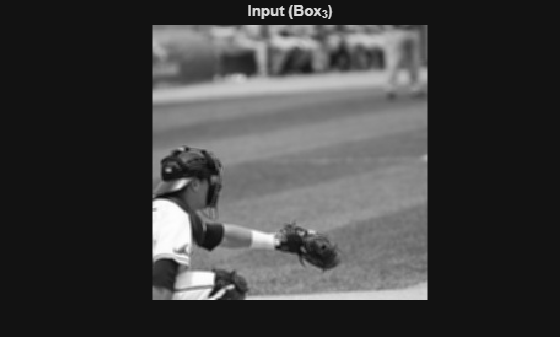

% Servono solo quelle di test
[~ , imgsTemp] = splitEachLabel(imgs, 0.7, "randomized");
[~, imgsTest] = splitEachLabel(imgsTemp, 0.5, "randomized");

I = readimage(imgsTest, 1);

figure
imshow(I)
title('Input (Box_3)');

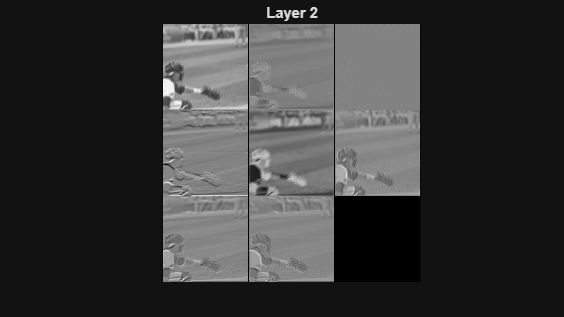

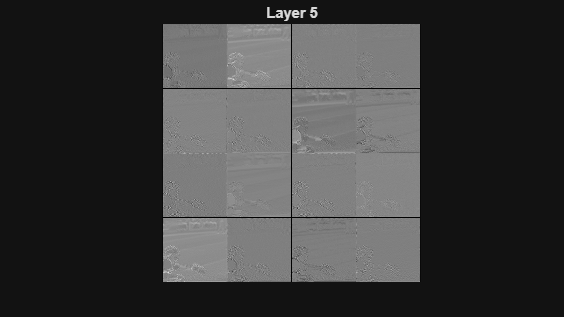

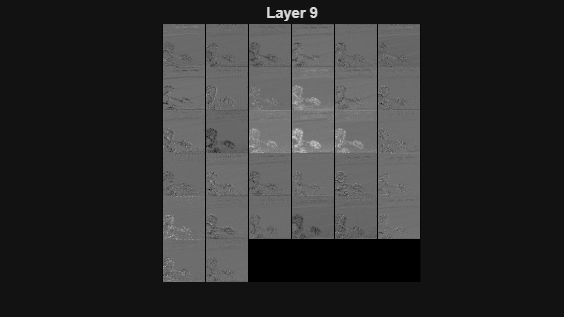

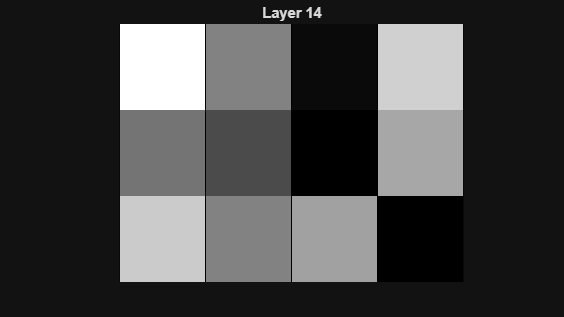

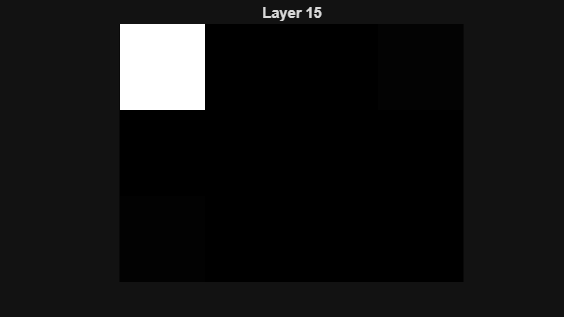


for i = 1:numel(layers)

    tipo = class(layers(i));

    if contains(tipo, 'Convolution2DLayer') || ...
       contains(tipo, 'FullyConnectedLayer') || ...
       contains(tipo, 'SoftmaxLayer')

        A = activations(S.net, I, i, 'OutputAs', 'channels');

        figure('Units','normalized','OuterPosition', [0 0 1 1])

        montage(mat2gray(A), ...
            'ThumbnailSize', [448 448], ...
            'BorderSize', [2 2]);

        title(sprintf('Layer %d', i));

    end
end


% Classe predetta
YPred = classify(S.net, I);

% Classe reale
YTrue = imgsTest.Labels(1);

% Confronto
if YPred == YTrue
    risultato = 'CORRETTA';
else
    risultato = 'ERRATA';
end

fprintf('Predetta: %s | %s', string(YPred), risultato);

Predetta: Box_3 | CORRETTA

# Risultati e metriche

DATASET PRINCIPALE

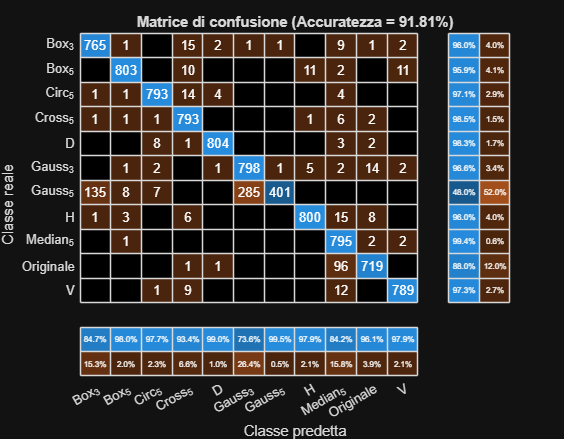

% Matrice di confusione
YPred = classify(S.net, imgsTest);
YTest = imgsTest.Labels;

accuracy = mean(YPred == YTest);

figure('Position', [100 100 900 700]);
cm = confusionchart(YTest, YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Classe predetta';
cm.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione (Accuratezza = %.2f%%)', accuracy * 100));


% Metriche di valutazione
C = confusionmat(YTest, YPred);

TP = diag(C);
FP = sum(C,1)' - TP;
FN = sum(C,2) - TP;
TN = sum(C(:)) - TP - FP - FN;

precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
specificity = TN ./ (TN + FP);
f1 = 2 * (precision .* recall) ./ (precision + recall);

precisionMean = mean(precision, 'omitnan');
recallMean = mean(recall, 'omitnan');
specificityMean = mean(specificity, 'omitnan');
f1Mean = mean(f1, 'omitnan');

fprintf('Valori medi:\n');

Valori medi:


fprintf('Precisione:  %.2f%%\n', precisionMean * 100);

Precisione:  92.92%


fprintf('Recall:      %.2f%%\n', recallMean * 100);

Recall:      91.92%


fprintf('Specificità: %.2f%%\n', specificityMean * 100);

Specificità: 99.18%


fprintf('F1-Score:    %.2f%%\n\n', f1Mean * 100);

F1-Score:    91.34%




% Metriche per classe
T = table(categories(YTest), specificity, f1, ...
    'VariableNames', {'Classe', 'Specificità', 'F1-Score'});

fprintf('Valori per classe:\n');

Valori per classe:


disp(T);

       Classe        Specificità    F1-Score
    _____________    ___________    ________

    {'Box_3'    }      0.98317          0.9 
    {'Box_5'    }      0.99804      0.96981 
    {'Circ_5'   }      0.99768       0.9736 
    {'Cross_5'  }      0.99316      0.95889 
    {'D'        }      0.99902       0.9865 
    {'Gauss_3'  }        0.965       0.8356 
    {'Gauss_5'  }      0.99975       0.6473 
    {'H'        }      0.99792       0.9697 
    {'Median_5' }      0.98182       0.9117 
    {'Originale'}      0.99645      0.91885 
    {'V'        }      0.99792      0.97588 



DATASET DI CONTRO-TEST

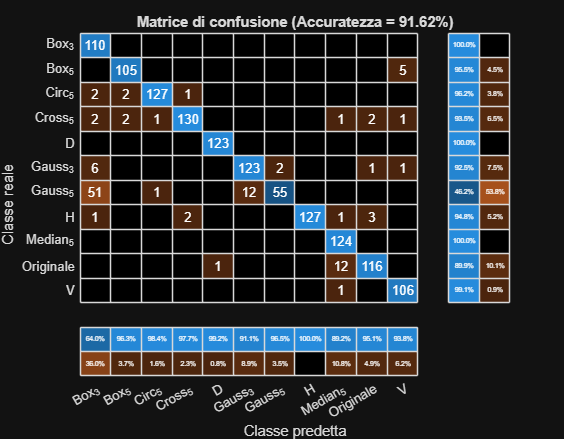

% Secondo dataset
YPred2 = classify(S.net, imgs2);
YTest2 = imgs2.Labels;

accuracy2 = mean(YPred2 == YTest2);

figure('Position', [100 100 900 700]);
cm2 = confusionchart(YTest2, YPred2);
cm2.RowSummary = 'row-normalized';
cm2.ColumnSummary = 'column-normalized';
cm2.XLabel = 'Classe predetta';
cm2.YLabel = 'Classe reale';
colormap(parula)
title(sprintf('Matrice di confusione (Accuratezza = %.2f%%)', accuracy2 * 100));


% Metriche di valutazione 2
C = confusionmat(YTest2, YPred2);

TP = diag(C);
FP = sum(C,1)' - TP;
FN = sum(C,2) - TP;
TN = sum(C(:)) - TP - FP - FN;

precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
specificity = TN ./ (TN + FP);
f1 = 2 * (precision .* recall) ./ (precision + recall);

% Media delle metriche 2
precisionMean = mean(precision, 'omitnan');
recallMean = mean(recall, 'omitnan');
specificityMean = mean(specificity, 'omitnan');
f1Mean = mean(f1, 'omitnan');

fprintf('Valori medi:\n');

Valori medi:


fprintf('Precisione:  %.2f%%\n', precisionMean * 100);

Precisione:  92.85%


fprintf('Recall:      %.2f%%\n', recallMean * 100);

Recall:      91.61%


fprintf('Specificità: %.2f%%\n', specificityMean * 100);

Specificità: 99.17%


fprintf('F1-Score:    %.2f%%\n\n', f1Mean * 100);

F1-Score:    91.01%




% Metriche per classe 2
T = table(categories(YTest2), specificity, f1, ...
    'VariableNames', {'Classe', 'Specificità', 'F1-Score'});

fprintf('Valori per classe:\n');

Valori per classe:


disp(T);

       Classe        Specificità    F1-Score
    _____________    ___________    ________

    {'Box_3'    }       0.9504      0.78014 
    {'Box_5'    }       0.9968       0.9589 
    {'Circ_5'   }      0.99837      0.97318 
    {'Cross_5'  }      0.99754      0.95588 
    {'D'        }      0.99919      0.99595 
    {'Gauss_3'  }      0.99022      0.91791 
    {'Gauss_5'  }      0.99839        0.625 
    {'H'        }            1      0.97318 
    {'Median_5' }      0.98786      0.94297 
    {'Originale'}      0.99513       0.9243 
    {'V'        }      0.99441      0.96364 



I valori tra i 2 dataset non risultano troppo distanti, quindi il modello riesce a generalizzare.

# 2 problemi 

Guardando entrambe le matrici si può notare che il kernel Gaussiano 5x5 è quello che causa più problemi, difatti viene confuso molto spesso sia con la sua versione 3x3 che con Box 3x3. Per capire il perché basta confrontare delle immagini elaborate con questi kernel, facendolo si può constatare come ad occhio nudo i risultati risultino estremamente simili. Aggiungendo il fatto che tutte le varie architetture provate hanno presentato il medesimo problema, pur in misura diversa, si può dire con una certa confidenza che questa problematica derivi dal kernel in sé. 

Un altro caso da considerare è quello della mediana, il fatto che la CNN classifichi alcune immagini inalterate con questa classe dipende dal funzionamento della mediana stessa. Se l'immagine a cui viene applicata è molto nitida (soprattutto con dei bordi ben definiti) si ha come effetto principale uno smussamento lungo i bordi mentre nel resto dell'immagine appare solamente una leggerissima attenuazione. 

Originale:

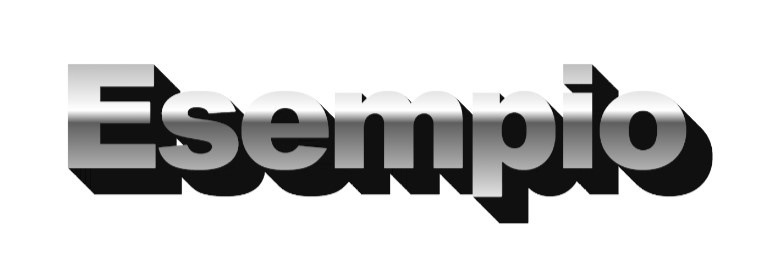

Mediana 5x5:

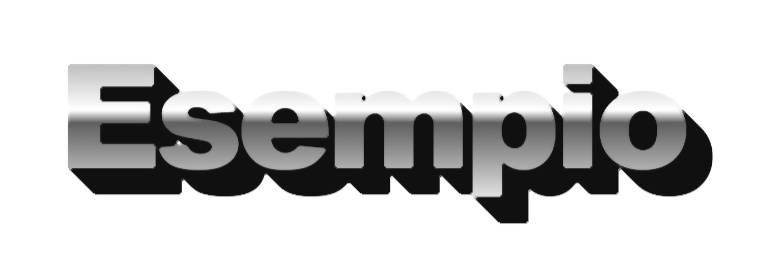

Box 3x3:

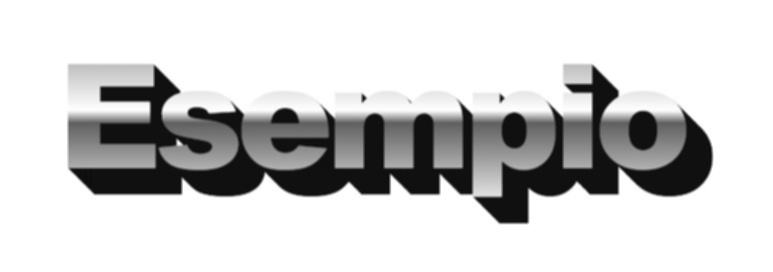

Gauss 3x3:

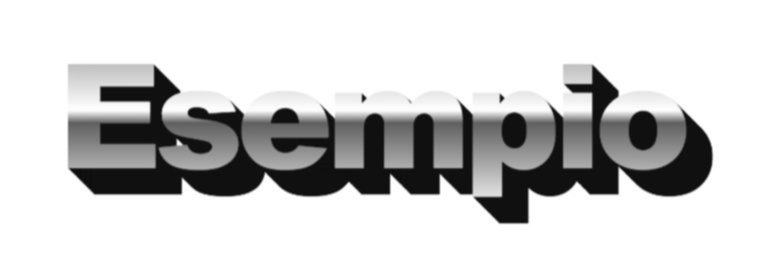

Gauss 5x5: